# Operating point

delta_vsc_0 = 0.55

delta_vsc_0 = 0.5500

P_aero_0

P_aero_0 = 0.6000


% dq/DqQ transformation matrices


## p/angle controller


k_d_vsm=30

k_d_vsm = 30


H_vsm = 3

H_vsm = 3

T_vsm = tf([omega_nom/(2*H_vsm*x_sys)],[1 k_d_vsm/(2*H_vsm) omega_nom/(2*H_vsm*x_sys)])

T_vsm =
 
        59.73
  -----------------
  s^2 + 5 s + 59.73
 
Continuous-time transfer function.
Model Properties



zeta_vsm = k_d_vsm/H_vsm*sqrt(2*H_vsm*x_sys/omega_nom)

zeta_vsm = 1.2939

nf_vsm = sqrt(omega_nom/(2*H_vsm*x_sys))

nf_vsm = 7.7288

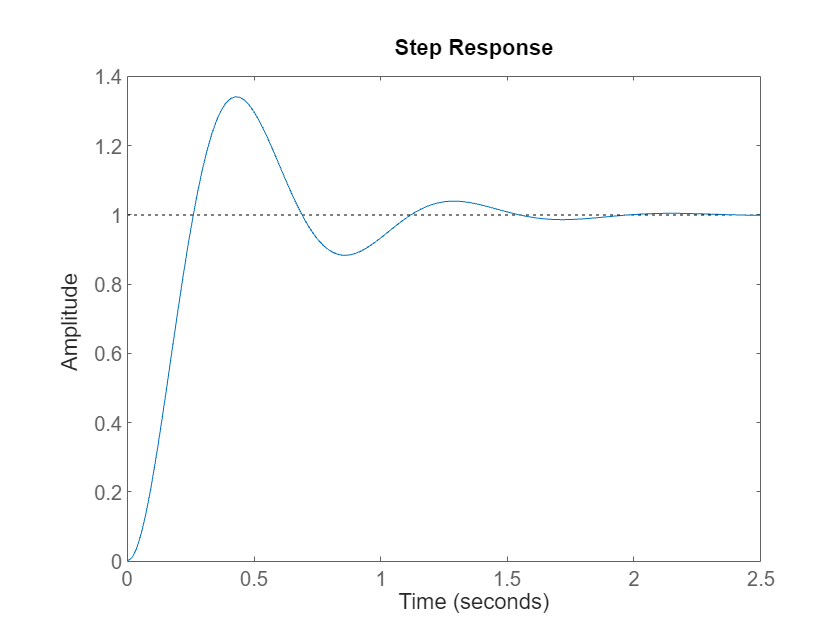

step(T_vsm)

## q controller droop


ki_q

ki_q = 314.1593

k_p_q_vsm = -0.05

k_p_q_vsm = -0.0500


% open loop

%closed loop 
T_q_vsm = tf([ki_q*k_p_q_vsm/x_sys],[1 ki_q+k_p_q_vsm*ki_q/x_sys])

T_q_vsm =
 
   -17.92
  ---------
  s + 296.2
 
Continuous-time transfer function.
Model Properties



%open loop Q_grid -> delta V_d_ref
T_e_vsm = tf([ki_q*k_p_q_vsm],[1 ki_q])

T_e_vsm =
 
   -15.71
  ---------
  s + 314.2
 
Continuous-time transfer function.
Model Properties


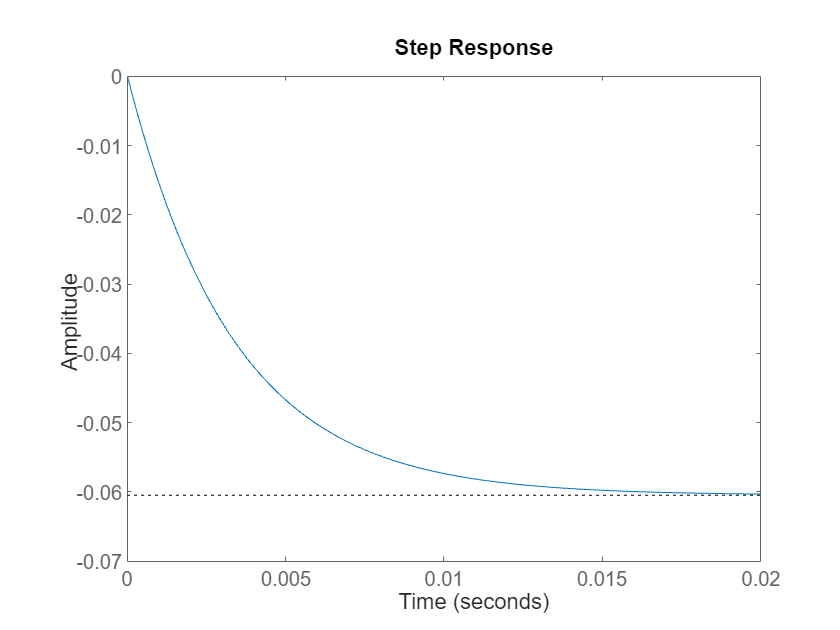


step(T_q_vsm)

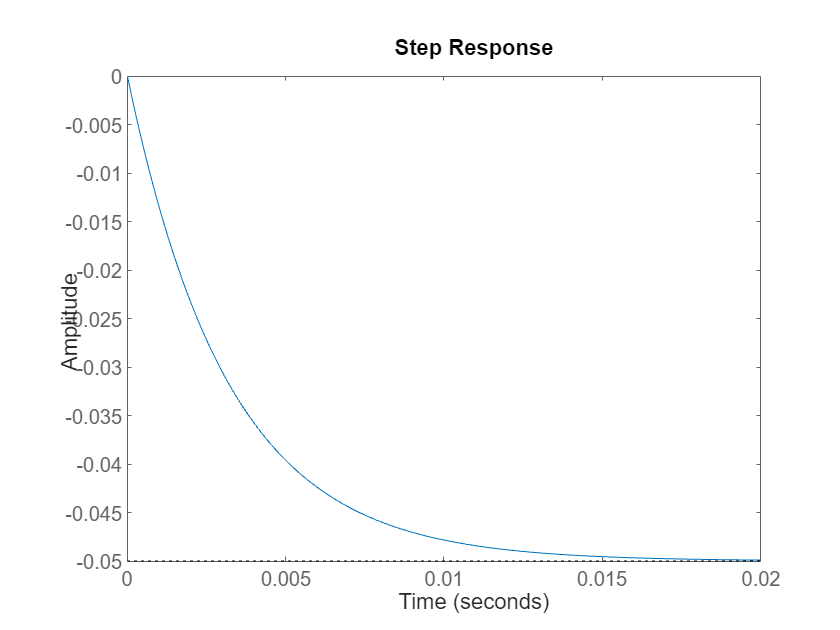

step(T_e_vsm)

## current control

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


ti = 5/f_sw

ti = 0.0017

G_plant = 1/(s*l_f+r_f)

G_plant =
 
           1
  -------------------
  0.1056 s + 0.005279
 
Continuous-time transfer function.
Model Properties


kp = l_f/ti

kp = 62.2908

ki = r_f/ti

ki = 3.1145

G_cc = (kp*s+ki)/s

G_cc =
 
  62.29 s + 3.115
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_cc = G_plant*G_cc/(1+G_plant*G_cc)

T_cc =
 
         6.577 s^3 + 0.6577 s^2 + 0.01644 s
  ------------------------------------------------
  0.01115 s^4 + 6.578 s^3 + 0.6577 s^2 + 0.01644 s
 
Continuous-time transfer function.
Model Properties



tf2ss([kp ki], [1 0])

ans = 0

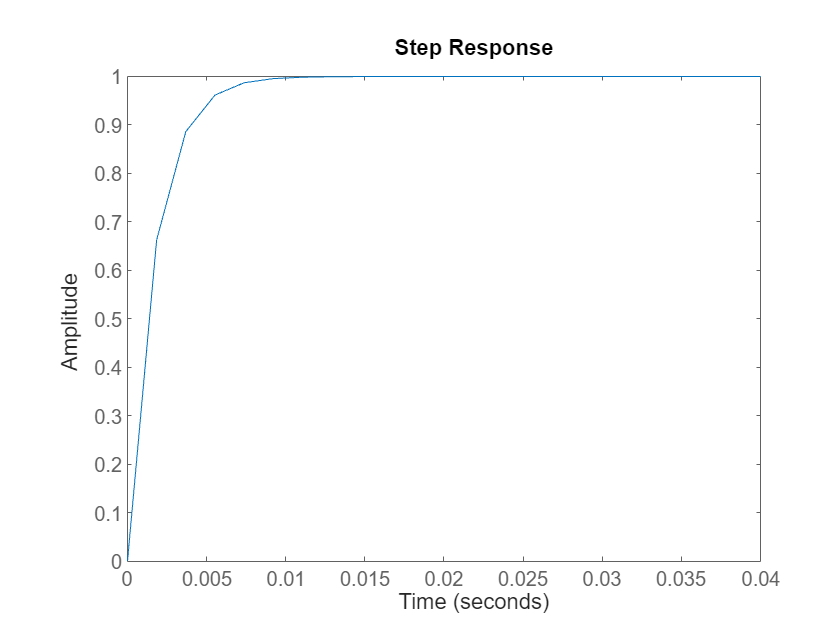


step(T_cc)

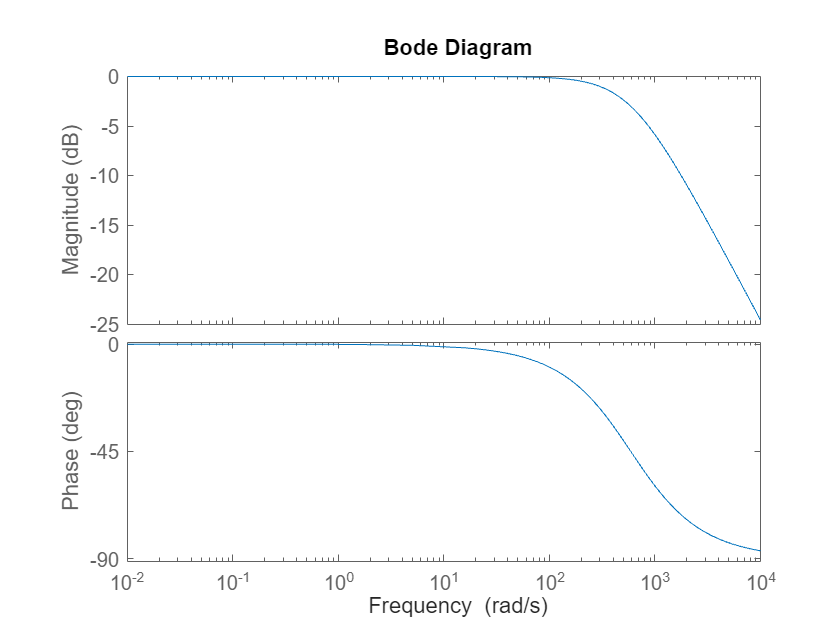

bode(T_cc)

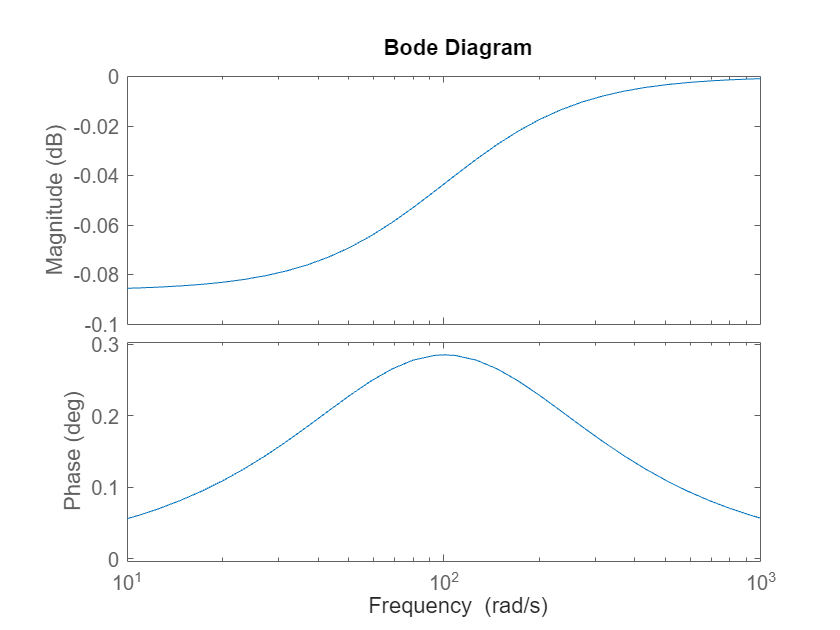

bode(((0.01*s+1)/0.01)/(1+(0.01*s+1)/0.01))     

## voltage control



z = 20

z = 20

asind((1-ti*z)/(1+ti*z)) % phase margin

ans = 69.1356

omega_c_vc = sqrt(z/ti)

omega_c_vc = 108.6278

k_vc = c_f*omega_c_vc

k_vc = 8.2231


%open
G_vc = k/(ti*c_f)*((s+z)/(s+1/ti))*1/s^2

G_vc =
 
  2.338e05 s + 4.676e06
  ---------------------
      s^3 + 590 s^2
 
Continuous-time transfer function.
Model Properties


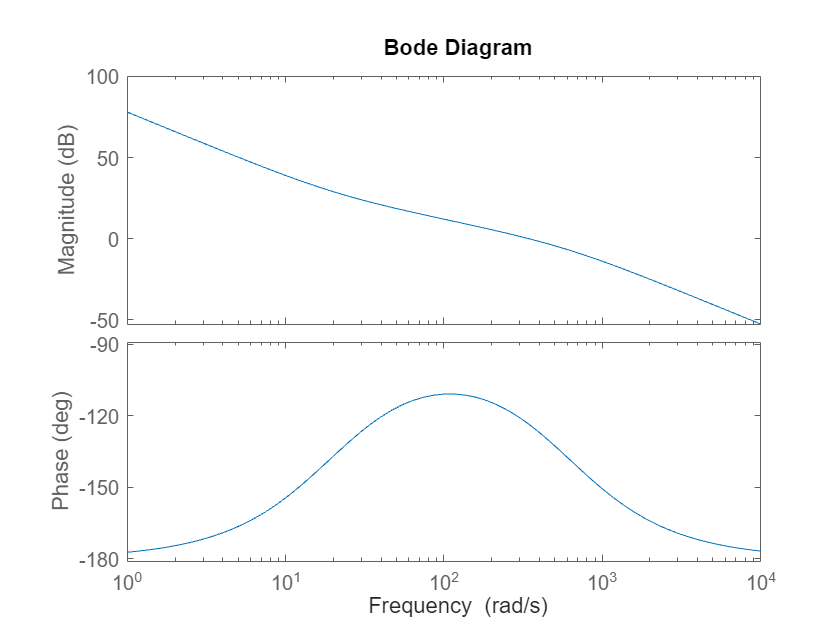

bode(G_vc)

% closed
T_vc = k/(ti*c_f)*((s+z)/(s+1/ti))*1/s^2/(1+k/(ti*c_f)*((s+z)/(s+1/ti))*1/s^2)

T_vc =
 
          2.338e05 s^4 + 1.426e08 s^3 + 2.759e09 s^2
  -----------------------------------------------------------
  s^6 + 1180 s^5 + 5.819e05 s^4 + 1.426e08 s^3 + 2.759e09 s^2
 
Continuous-time transfer function.
Model Properties


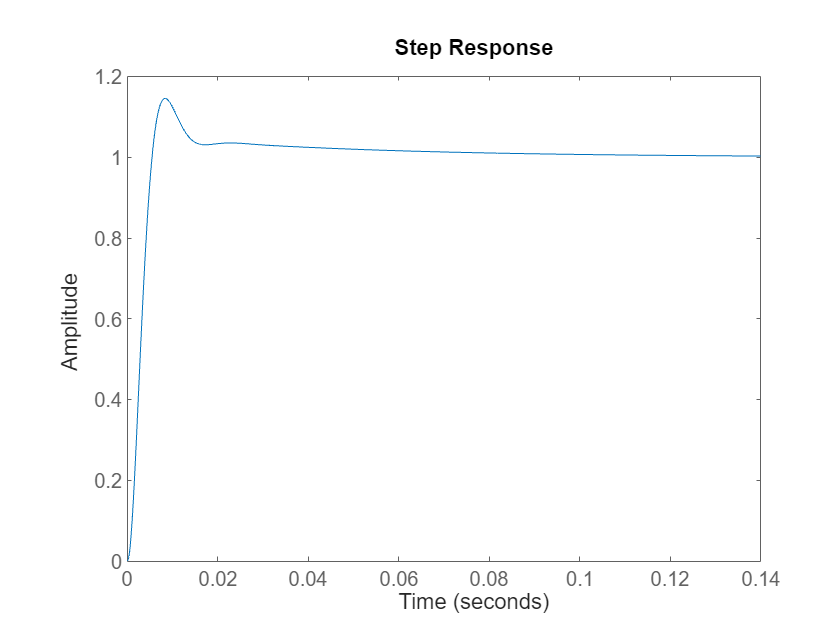

    step(T_vc)

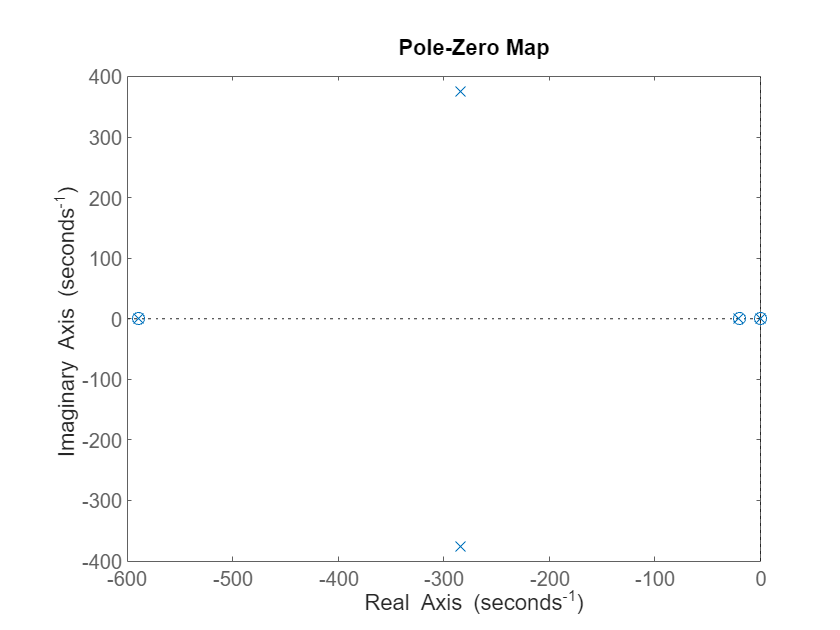

    pzmap(T_vc)

## Detailed dc voltage controller


c_dc =0.00666540000000 % pu  0.47 % aggregated

c_dc = 0.0067

% negative 1 is steady state wind power pu
% cross over frequency is 20 rad/s
    zigma_dc = 2*l_f*(1)/(3*1^2)

zigma_dc = 0.0704

k0 = 1.5

k0 = 1.5000

G_dc_pre =-k0*2/c_dc*(zigma_dc*s+1)/(s^2*(0.01*s+1)) 

G_dc_pre =
 
  -31.68 s - 450.1
  ----------------
   0.01 s^3 + s^2
 
Continuous-time transfer function.
Model Properties


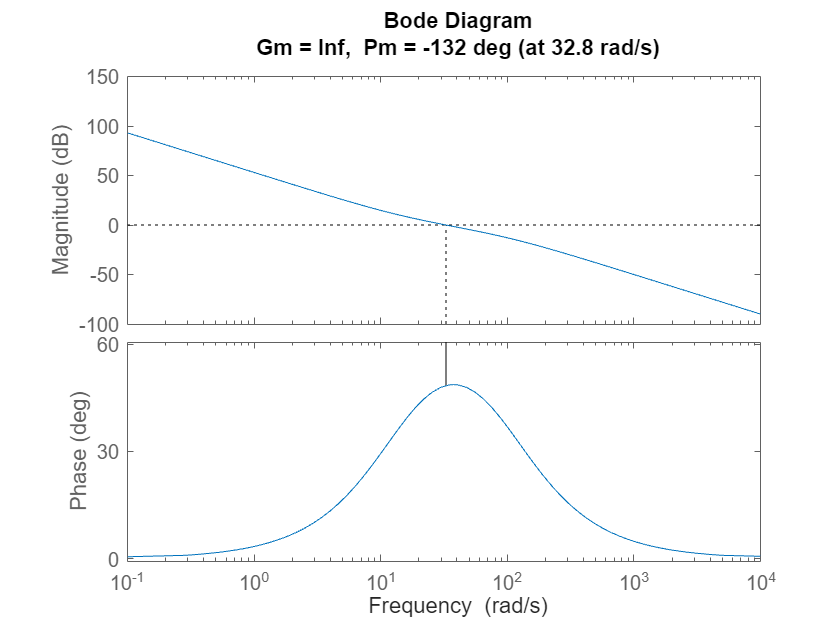

margin(G_dc_pre)

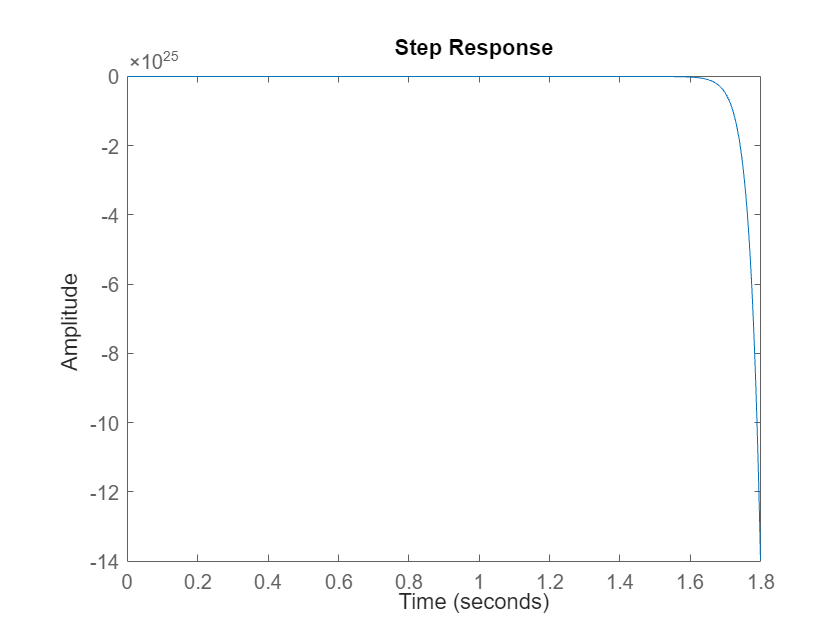

step(G_dc_pre/(1+G_dc_pre))


n0 = 1/(10^(-13/20));

a = 50; 
asind((a-1)/(a+1)) % phase margin

ans = 73.9011

p = sqrt(a)*23;
N = -n0*(s+p/a)/(s+p)

N =
 
  -4.467 s - 14.53
  ----------------
     s + 162.6
 
Continuous-time transfer function.
Model Properties


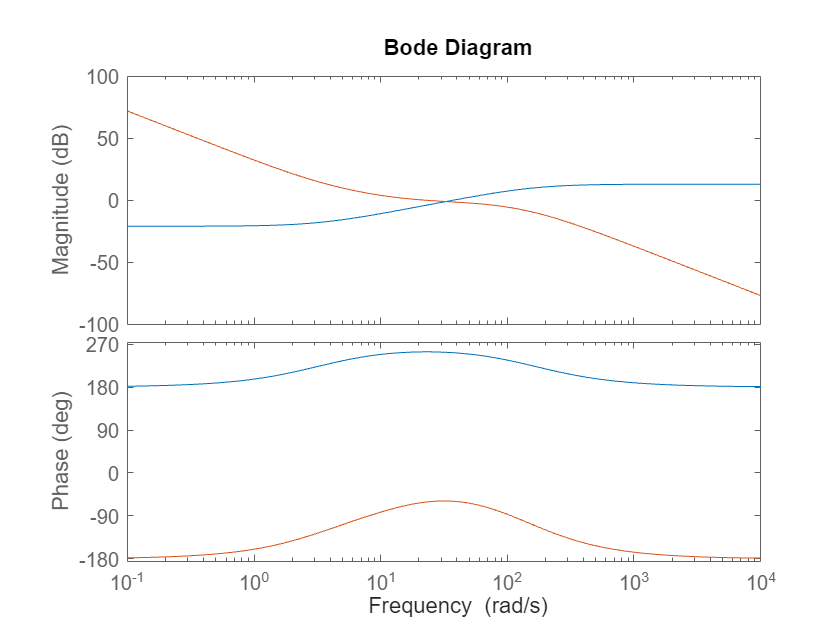

bode(N,N*G_dc_pre)

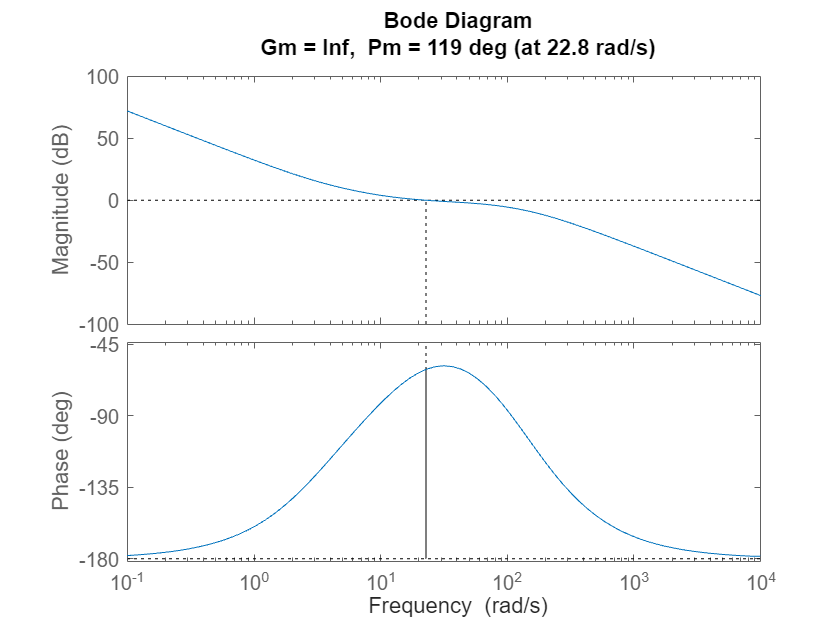

margin(N*G_dc_pre)

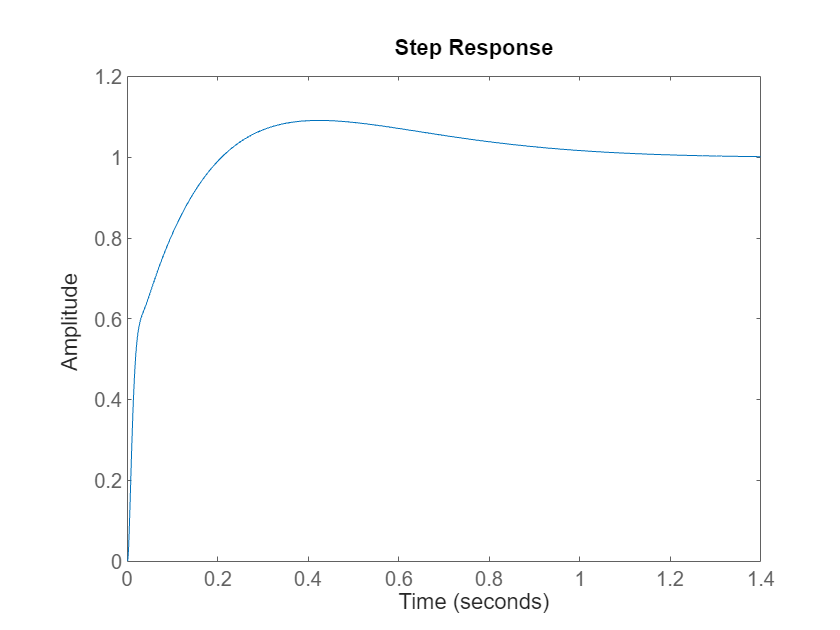

step(G_dc_pre*N/(1+G_dc_pre*N))


G_dc = N*k0/s 

G_dc =
 
  -6.7 s - 21.79
  --------------
  s^2 + 162.6 s
 
Continuous-time transfer function.
Model Properties


G_dc_num = get(G_dc,'Numerator')

G_dc_num = 1×1 cell array
    {[0 -6.7003 -21.7939]}


G_dc_denom = get(G_dc,'Denominator')

G_dc_denom = 1×1 cell array
    {[1 162.6346 0]}


T_dc = -2/c_f*(zigma_dc*s+1)/s

T_dc =
 
  -1.86 s - 26.42
  ---------------
         s
 
Continuous-time transfer function.
Model Properties


T_dc_num = get(T_dc,'Numerator')

T_dc_num = 1×1 cell array
    {[-1.8596 -26.4201]}


T_dc_denom = get(T_dc,'Denominator')

T_dc_denom = 1×1 cell array
    {[1 0]}


##  dc voltage controller TV


C_dc_TV = 0.3 % F

C_dc_TV = 0.3000

V_dc

V_dc = 1.1268e+03

% negative 1 is steady state wind power pu
% cross over frequency is 20 rad/s

G_dc_pre =1/(C_dc*s*V_dc) 

G_dc_pre =
 
    1
  ------
  2236 s
 
Continuous-time transfer function.
Model Properties


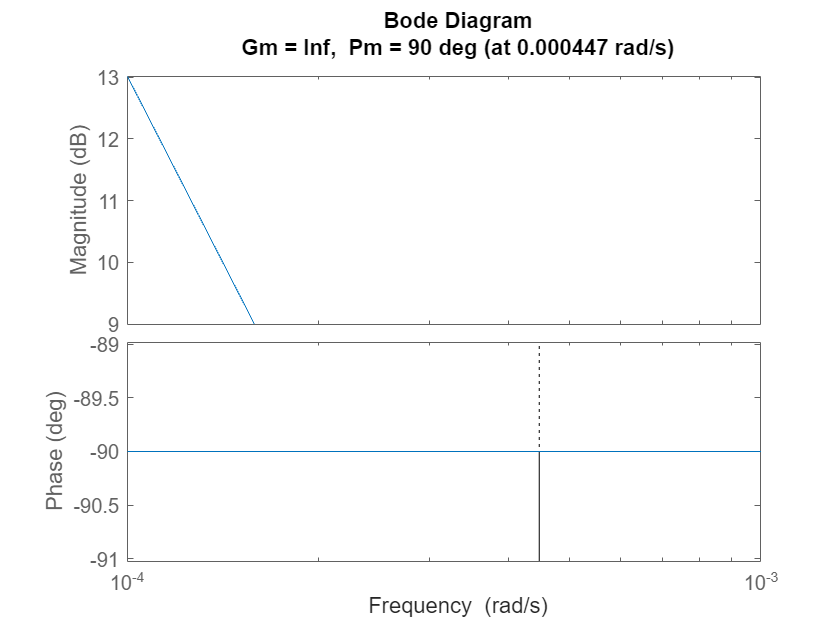

margin(G_dc_pre)

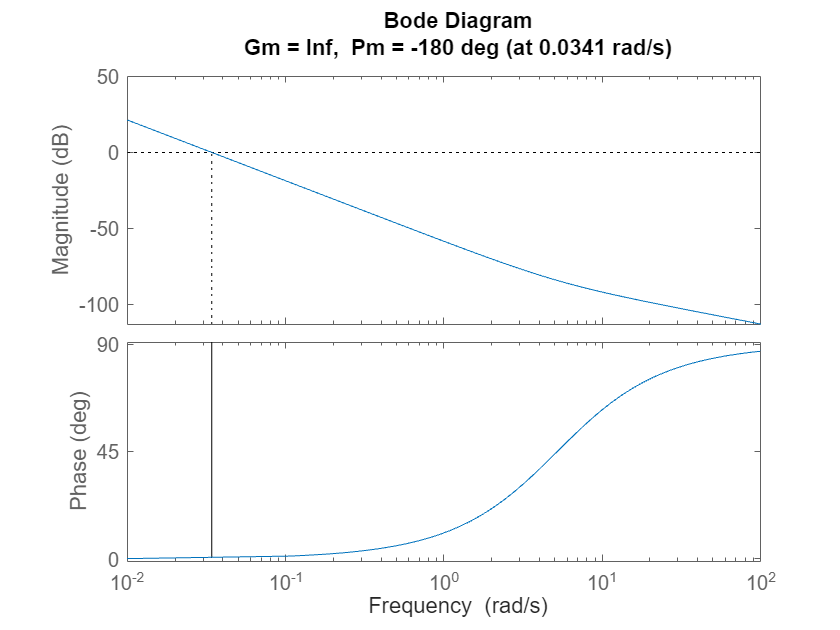

% step(G_dc_pre/(1+G_dc_pre))

kp_dc = 0.78;
ki_dc = 0.85;
margin(G_dc_pre*G_dc)

G_dc = 1*(kp_dc + ki_dc/s)

G_dc =
 
  0.78 s + 0.85
  -------------
        s
 
Continuous-time transfer function.
Model Properties


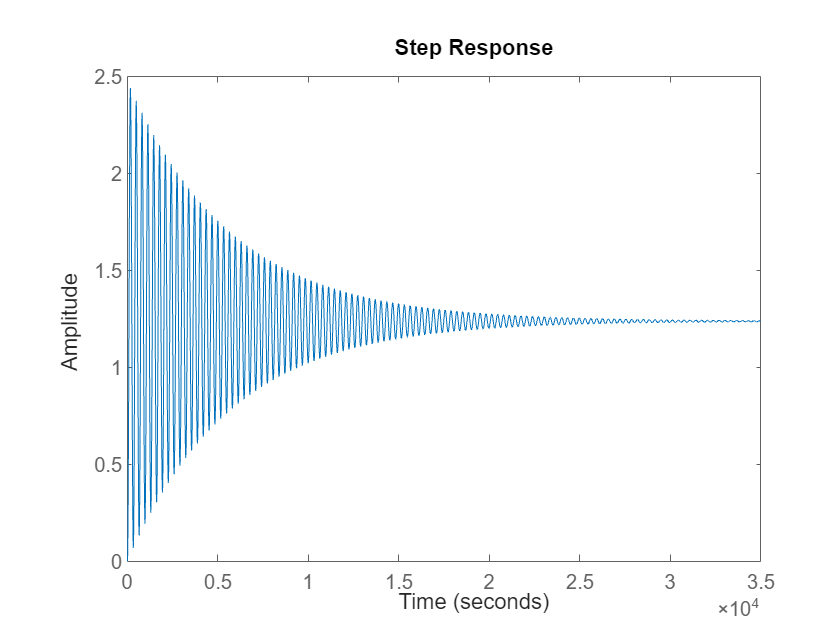



% a = 50; 
% asind((a-1)/(a+1)) % phase margin
% p = sqrt(a)*23;
% N = -n0*(s+p/a)/(s+p)
% bode(N,N*G_dc_pre)
% margin(N*G_dc_pre)
% step(G_dc_pre*N/(1+G_dc_pre*N))
step(G_dc_pre*G_dc/(1+G_dc_pre*G_dc)*K_TP)

G_dc_num = get(G_dc,'Numerator')

G_dc_num = 1×1 cell array
    {[0.7800 0.8500]}


G_dc_denom = get(G_dc,'Denominator')

G_dc_denom = 1×1 cell array
    {[1 0]}


T_dc = G_dc_pre

T_dc =
 
    1
  ------
  2236 s
 
Continuous-time transfer function.
Model Properties


T_dc_num = get(T_dc,'Numerator')

T_dc_num = 1×1 cell array
    {[0 1]}


T_dc_denom = get(T_dc,'Denominator')

T_dc_denom = 1×1 cell array
    {[2.2365e+03 0]}


## simplified dc controller

c_dc = 0.47; % pu  aggregated
% cross over frequency is 20 rad/s
dc_plant = -1/c_dc*1/s

dc_plant =
 
  -2.128
  ------
    s
 
Continuous-time transfer function.
Model Properties


kp_dc = 20;
ki_dc = 5;
G_dc = -1*(kp_dc + ki_dc/s)

G_dc =
 
  -20 s - 5
  ---------
      s
 
Continuous-time transfer function.
Model Properties


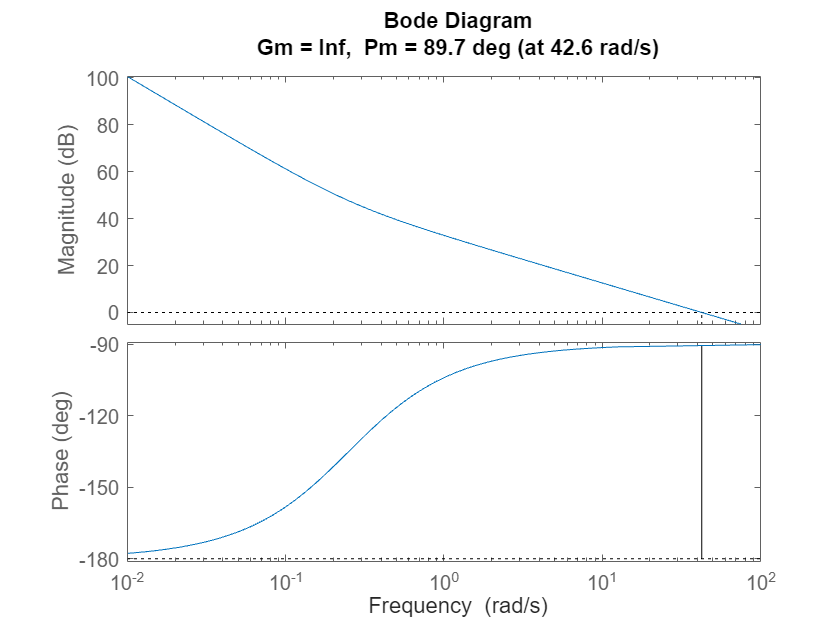


margin(G_dc*dc_plant)

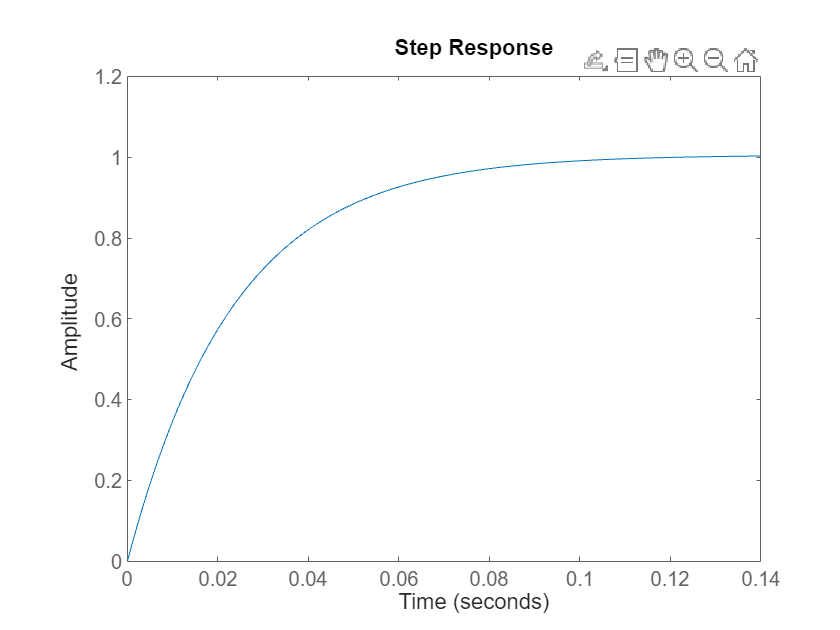

step(G_dc*dc_plant/(1+G_dc*dc_plant))


G_dc_num = get(G_dc,'Numerator')

G_dc_num = 1×1 cell array
    {[-20 -5]}


G_dc_denom = get(G_dc,'Denominator')

G_dc_denom = 1×1 cell array
    {[1 0]}


T_dc = dc_plant

T_dc =
 
  -2.128
  ------
    s
 
Continuous-time transfer function.
Model Properties


T_dc_num = get(T_dc,'Numerator')

T_dc_num = 1×1 cell array
    {[0 -2.1277]}


T_dc_denom = get(T_dc,'Denominator')

T_dc_denom = 1×1 cell array
    {[1 0]}


## Linearized mppt

omega_WTR_0*omega_WTR_n

ans = 0.6399

mppt_gain = 3/2*rho*pi*R_WTR^5*C_p_opt/lambda_opt^3*(omega_WTR_0*omega_WTR_n)^2

mppt_gain = 3.7182e+07

% torsional vibration paper
% v_w_TV = 10
% lambda_opt_TV = 7
% c_p_opt_TV = 0.44
% R_WTR_TV = 63
% omega_WTR_0_TV = v_w_TV*lambda_opt_TV/R_WTR_TV
% omega_WTR_0_TV/1.27

0.5*rho*pi*R_WTR_TV^2*c_p_opt_TV*v_w_TV^3

ans = 3.3604e+06

0.5*rho*pi*R_WTR_TV^2*c_p_opt_TV*(omega_WTR_0_TV*R_WTR_TV/lambda_opt_TV)^3

ans = 3.3604e+06


15*pi/180

ans = 0.2618

## Linearized two mass model

lambda_op = omega_WTR_0*R_WTR/(v_w_0*v_w_n)

lambda_op = 11.1156

k_tur=-0.04206446159

k_tur = -0.0421

A_m = 1/(2*H_WTR*s)

A_m =
 
    1
  -----
  4.2 s
 
Continuous-time transfer function.
Model Properties


A_g = 1/(2*H_gen*s)

A_g =
 
    1
  -----
  1.8 s
 
Continuous-time transfer function.
Model Properties


A_s = c_drt+k_drt/s

A_s =
 
  s + 280
  -------
     s
 
Continuous-time transfer function.
Model Properties



M_gr = A_s*((A_m*A_s)/(1+A_m*A_s-A_m*k_tur)-1)

M_gr =
 
  -74.09 s^6 - 2.075e04 s^5 - 207.8 s^4
  -------------------------------------
    74.09 s^6 + 18.38 s^5 + 4939 s^4
 
Continuous-time transfer function.
Model Properties


M_gr_num = get(M_gr,'Numerator')

M_gr_num = 1×1 cell array
    {[-74.0880 -2.0745e+04 -207.7648 0 0 0 0]}


M_gr_denom = get(M_gr,'Denominator')

M_gr_denom = 1×1 cell array
    {[74.0880 18.3820 4.9392e+03 0 0 0 0]}



K_Tomega = -P_aero_0/omega_WTR_0^2

K_Tomega = -0.9185

K_TP = 1/omega_WTR_0

K_TP = 1.2373